clearvars;
addpath("Spherical Harmonics/helperFunctions/");
addpath("Image Source Method/");

# Least Square Method - Image Source Method

### Initial Parameters

n = 3; spacing = 0.01;
room = [6,6,5];
order = 5

order = 5

beta = [0.8,0.75,0.85,0.77,0.1,0.1]; alpha = 1-beta.^2;
f = 200; c = 343; omega = 2*pi*f ; phase = 0;
rho_k = omega/c;
S = my_sph2cart(deg2rad(90),deg2rad(405),2);
mag = 10;
[rho_s,the_s,phi_s] = my_cart2sph(S);
rx = -n:spacing:n;
ry = rx;
sz = [length(ry) length(rx)];
rz = zeros(size(rx));
r = [rx;ry;rz];
R = 0.5; % region of interrest
L = ceil(exp(1)*rho_k*R/2);
N = L-1;

### Monopole Wave - Energy

According to http://www.apsipa.org/proceedings_2015/pdf/223.pdf

We can express the average sound energy within the control region $S$ as


$$\int_S|P(\mathbf x)|^2dS = \int_0^R\int_0^\pi\int_0^{2\pi}P(\mathbf x)\overline{P(\mathbf x)}r^2dr\sin\theta d\theta d\phi = \sum_{n,m}a_{nm}\overline{a_{nm}}\int_0^Rj_n^2(kr)r^2dr$$



$$SPL=10log\bigg(\frac{P}{P_{ref}}\bigg)$$


where


$$P_{ref} = 20\mu P$$


$P = 

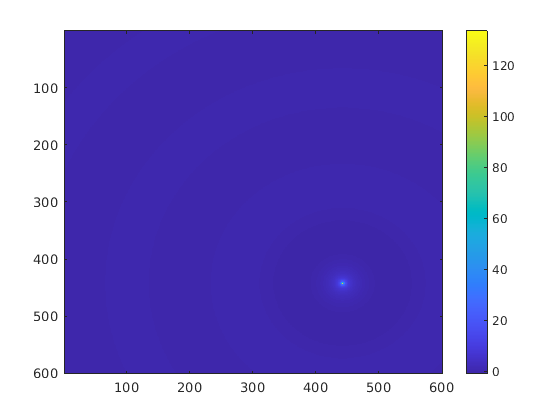

wave1 = monopoleWave(S,r,mag,rho_k,0);
figure;
imagesc(real(wave1)); colorbar;

find(isnan(real(wave1)))


ans =

  0×1 empty double column vector



### Monopole Wave - Image Source Method

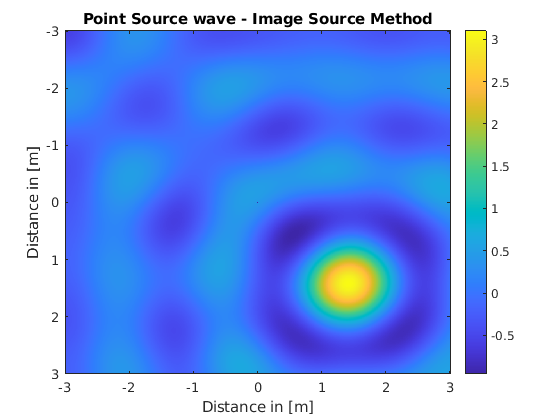

figure;
wave = ISM2d(rx,ry,rz,S,room,mag,phase,omega,c,alpha,order,spacing,1);

figure;


sound enegry density is defined by


$$E = w=\frac{pv}{c}$$


where 

$p$ is the sound pressure

$c$ is the speed of sound

according to https://edisciplinas.usp.br/pluginfile.php/4983673/mod_resource/content/0/Fundamentals%20of%20Acoustics%204ed-Cap5.pdf

$v= p/z$ is the particle velocity

$z=\rho_0c\cos\theta e^{j\theta}$ is the acoustic impedance

The sound enery density level is given by


$$L(E) = 10\log_{10}\bigg(\frac{E_1}{E_0}\bigg)dB$$


where

$E_0=10^{-12}Pa$ is the standard reference sound energy density

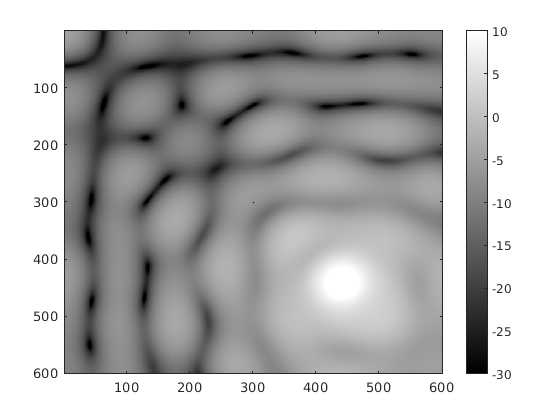

Lp = 10*log10(abs(wave1).^2);
imagesc(Lp); colorbar; colormap gray;
caxis([-30 ,10]);

### Microphone Array 

waveFun = @(R,the,phi) ISMspherical(rho_s,the_s,phi_s,R,the,phi,room,mag,phase,omega,c,alpha,order);
[Blm,mic] = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,0);
B = Blm(1,1);
for idl=2:(L+1)
    l=idl-1;
    for idm=1:(2*l+1)
        B = [B Blm(idl,idm)];
    end
end
B = B.';

### Loudspeaker

[nlspkr,lspkr] = loudspeaker_positions(n,1);

### 3D Plot

setupPlot(wave,mic,lspkr,S,R,n,spacing,3,1);

### 2D Plot with wave

setupPlot(wave,mic,lspkr,S,R,n,spacing,2,1);

### Loudspeaker Coefficients

Nulm = zeros(L+1,2*L+1,nlspkr);
for i = 1:size(lspkr,2)
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    waveFun = @(R,the,phi) ISMspherical(rho_i,the_i,phi_i,R,the,phi,room,mag,phase,omega,c,alpha,order);
    [Nulm(:,:,i),~] = harmonicCoefficients(L,R,rho_k,N,waveFun,n,wave,0);
end

Nu = zeros(size(B,1),size(lspkr,2));
for i = 1:nlspkr
    id = 1;
    for idl=1:(L+1)
        l = idl-1;
        for idm=1:(2*l+1)
            Nu(id,i) = Nulm(idl,idm,i);
            id = id+1;
        end
    end
end

### Louspeaker Driving Signal

d = -pinv(Nu)*B;

###  Secondary Sound Field

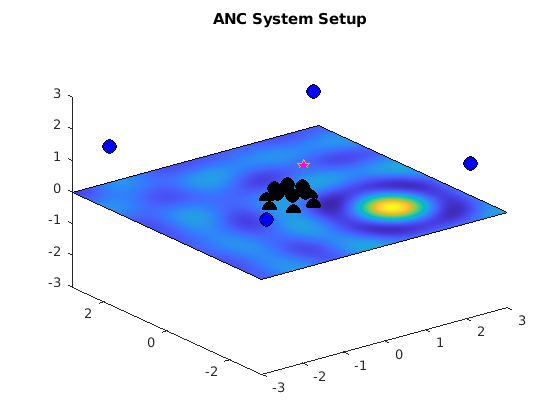

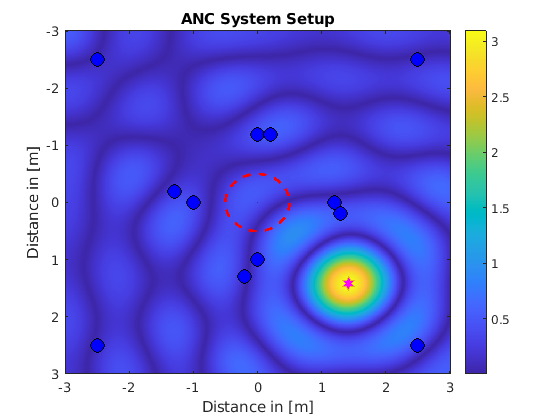

s_xk = zeros(sz(1),sz(2),nlspkr);
h = waitbar(0,"init");
for i=1:nlspkr
    
    [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
    for idy = 1:sz(1)
        for idx = 1:sz(2)
            [rho,the,phi] = my_cart2sph([rx(idx);ry(idy);0]);
            G = ISMspherical(rho_i,the_i,phi_i,rho,the,phi,room,mag,phase,omega,c,alpha,order);
            s_xk(idy,idx,i) = G*d(i);
        end
    end
    waitbar(i/size(lspkr,2),h,"loading...");
     
end

close(h);
% s_xk = zeros(sz(1),sz(2),nlspkr);
% h = waitbar(0,"init");
% for i=1:nlspkr
%     [rho_i,the_i,phi_i] = my_cart2sph(lspkr(:,i));
%     s_xk_xy = zeros(sz(1),sz(2));
%     parfor idy = 1:sz(1)
%         s_xk_x = zeros(1,sz(2));
%         for idx = 1:sz(2)
%             [rho,the,phi] = my_cart2sph([rx(idx);ry(idy);0]);
%             G = ISMspherical(rho_i,the_i,phi_i,rho,the,phi,room,mag,phase,omega,c,alpha,order);
%             s_xk_x = G*d(i);
%         end
%         s_xk_xy(idy,:) = s_xk_x;
%     end
%     s_xk(:,:,i) = s_xk_xy;
%     waitbar(i/size(lspkr,2),h,"loading...");
% end
% close(h);

### Residual Noise Field

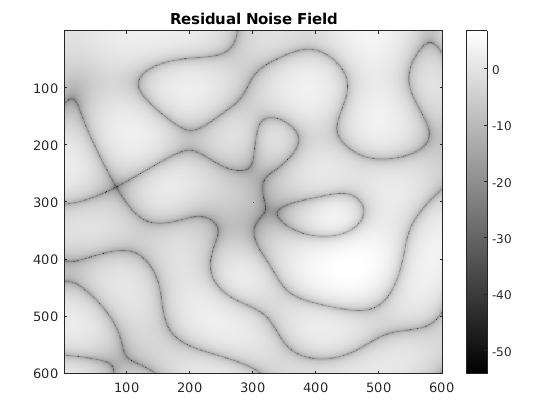

e = wave;
for i=1:nlspkr
    e = e+s_xk(:,:,i);
end
figure;
wave1 = imag(e+s_xk(:,:,12));
%wave1(find(real(wave1) >= 10)) = imag(wave1(find(real(wave1) >= 10)));
Lp = 10*log10(abs(wave1));
imagesc(Lp); colorbar; colormap gray;
%setupPlot(Lp,mic,lspkr,S,R,n,spacing,2,1);
title("Residual Noise Field")